# Try to solve the equation:


$$\exp(-ix) = 1-\frac{2A}{x}$$


Num_A = 100;
v_ind = -10:10;
Num_ind = length(v_ind);

vA = linspace(0,1j,Num_A);
m_r = zeros(Num_A,Num_ind);
m_im = zeros(Num_A,Num_ind);
for k=1:Num_A
    A = vA(k);
    myroot = fn_solve1(A,v_ind);
    m_r(k,:) = real(myroot);
    m_im(k,:) = imag(myroot);
    disp(k);   
end

     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



    11



    12



    13



    14



    15



    16



    17



    18



    19



    20



    21



    22



    23



    24



    25



    26



    27



    28



    29



    30



    31



    32



    33



    34



    35



    36



    37



    38



    39



    40



    41



    42



    43



    44



    45



    46



    47



    48



    49



    50



    51



    52



    53



    54



    55



    56



    57



    58



    59



    60



    61



    62



    63



    64



    65



    66



    67



    68



    69



    70



    71



    72



    73



    74



    75



    76



    77



    78



    79



    80



    81



    82



    83



    84



    85



    86



    87



    88



    89



    90



    91



    92



    93



    94



    95



    96



    97



    98



    99



   100



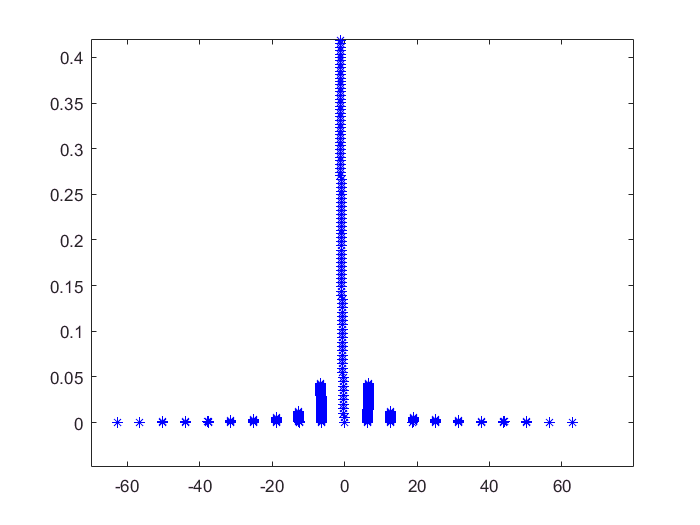


for k=1:Num_A
   
   plot(m_r(k,:),m_im(k,:),'b*');
   hold on;
    
end

res = fn_solve1(1j,0)

res =   -1.2366 + 0.4257i


function result = fn_F(x,A)
    result = x.*exp(-1j*x) - x + 2*A;
end

function result = fn_dF(x)
    result = -1 + exp(-1j*x) - 1j*x.*exp(-1j*x);
end

function result = fn_ddF(x)
    result = -(2j+x).*exp(-1j*x);
end

function result = fn_step(x0,A)
    
   a = 1/2*fn_ddF(x0);
   b = fn_dF(x0);
   c = fn_F(x0,A);
    
   sqd = sqrt(b.^2 - 4.*a.*c);
   
   x1 = 1./2./a.*(-b + sqd);
   x2 = 1./2./a.*(-b - sqd);
   
%    if abs(x2)<abs(x1)
%        step_x = x2;
%    else
%        step_x = x1;
%    end

   t_logical = abs(x2)<abs(x1);
   step_x = zeros(1,length(x0));
   step_x(t_logical) = x2(t_logical);
   step_x(~t_logical) = x1(~t_logical);
   
   result = x0 + step_x;
   
end


function result = fn_solve1(A,quantum_number)

vA = linspace(0.001,A,100);
x = quantum_number * 2*pi;
for k=1:100
    
   a = vA(k);
   
   while 1
       x = fn_step(x,a);
        if norm(fn_F(x,a))<1e-8
           break;
       end
   end
   
end

result = x;

end
